# Sistemas de ecuaciones no lineales

Contrario a sistemas de ecuaciones lineales, no podemos graficar fácilmente sistemas de ecuaciones no lineales, en vez de utilizar `fplot`, utilizaremos `fimplicit`

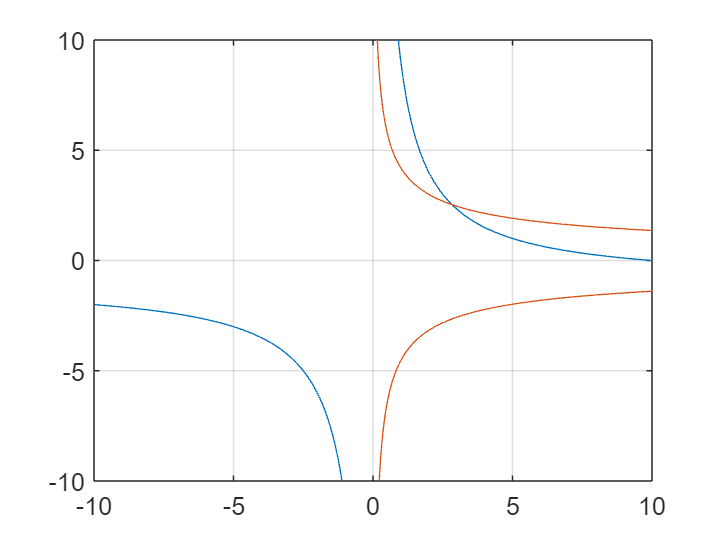

f1 = @(x1, x2) x1 + x1.*x2 - 10;
f2 = @(x1, x2) x2 + 3*x1.*x2.^2 - 57;

fimplicit(f1, [-10 10])
hold on
fimplicit(f2, [-10 10])
hold off
grid on

g = @(x) [(13-x(1)^2 - 2*x(2)^2)/10;
           (6-2*x(1)^3+x(2)^2)/5];

x = [0; 0];
i = 0;
condition = true;
while condition
    xp = x;
    x = g(x);
    
    i = i+1;
    condition = norm((x-xp)./x, Inf) > 0.5e-5 && i < 100;
end

i = 55

x =     1.0000
    1.0000
